## Daniels input

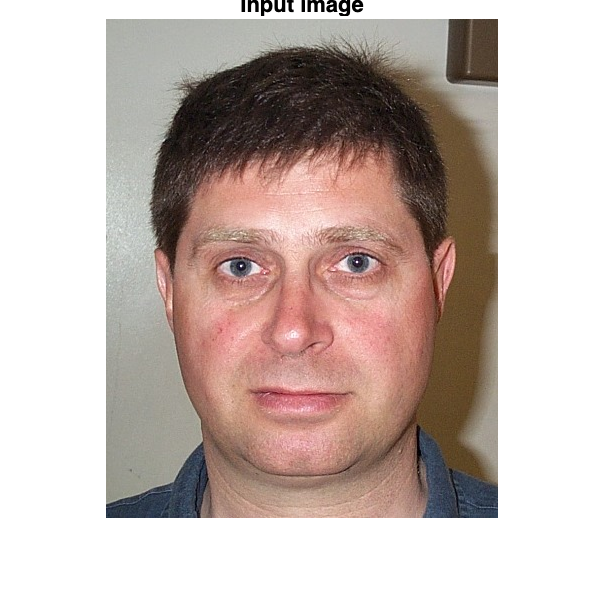

% DB1
inputImage = imread('images/DB1/db1_01.jpg');

% DB2
% queryImagePath = 'images/DB2/bl_01.jpg';
imshow(inputImage);
title('Input image');

editedImage = degrade_img(inputImage);

rotationAngle = -4

% editedImage = inputImage;

## Compensation

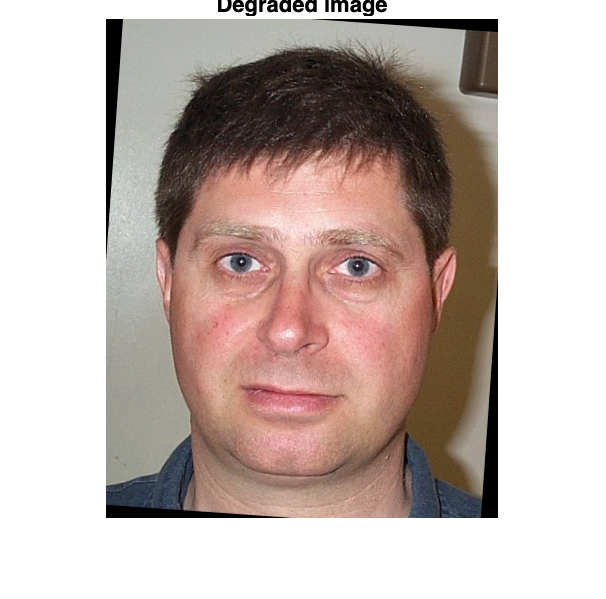

imshow(editedImage);
title('Degraded image');


% editedImage = tone_compensation(editedImage);
% imshow(editedImage);
% title('Compensated image');

## "Database"

addpath('functions');

% Parameters
numImages = 16;
commonSize = [400, 300];
folderPath = 'images/DB1';
threshold = 1.0;  % Threshold for variance explanation

% Load and preprocess images
[dataMatrix, imageFiles] = load_and_preprocess_images(folderPath, commonSize);

% Perform PCA
[score, meanFace, numEigenfaces, eigenfaces, numComponentsRequired] = perform_pca(dataMatrix, threshold);

% Display number of components required
fprintf('Number of principal components needed: %d\n', numComponentsRequired);

Number of principal components needed: 15


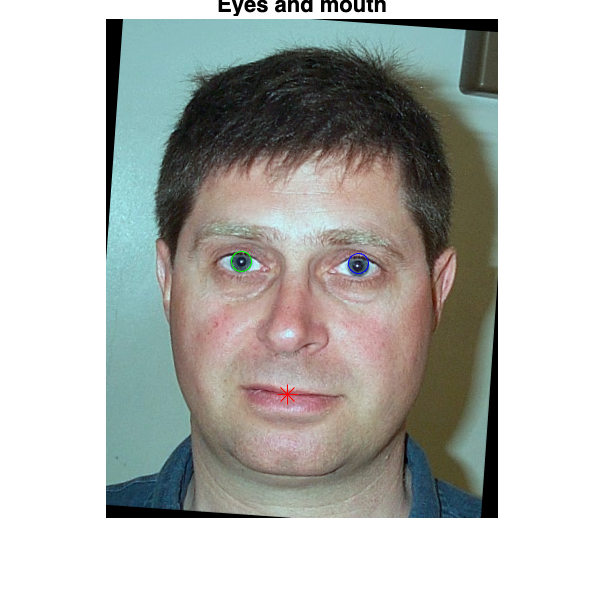

[rows, cols, ~] = size(editedImage);

% Calculate the cropping margins (10% on each side)
cropMarginRows = round(0.1 * rows);
cropMarginCols = round(0.1 * cols);

% Crop the image
% editedImage = imcrop(editedImage, [cropMarginCols, cropMarginRows, cols - 2*cropMarginCols, rows - 2*cropMarginRows]);

eyes = find_eyes(editedImage);

% Project query image onto eigenfaces
imshow(editedImage);

img_comp = rotation_compensation(editedImage, eyes);
imshow(img_comp)

queryWeights = project_onto_eigenfaces(img_comp, eigenfaces, meanFace);

% Recognize the face
recognize_face(queryWeights, score, numImages, folderPath, imageFiles, numEigenfaces);